# CBF for Industrial Manipulator(PUMA560) using CVXPY

% 2024-08-14
% Reference: F. Ferraguti et al., “Safety and Efficiency in Robotics: The Control Barrier Functions Approach,” IEEE Robot. Automat. Mag., vol. 29, no. 3, pp. 139–151, Sep. 2022, doi: 10.1109/MRA.2022.3174699.

clc
clear
close all

clear classes;

mod = py.importlib.import_module('manipulator_CBF_cvxpy');
py.importlib.reload(mod);

## Model parameters and initial conditions

u_des = [1 0 0 0 0 0]'; % Desired q'
init_q = [0 0 0 0 0 0]';
Tf = 3; % Duration
Ts = 0.001; % Sample time
p_obs = [0 0.4 1]; % Position of the obstacle
R = 0.1; % Radious of the obstacle
R_w = 0.1; % Radious of the wrist of robot


## $\gamma$=1, 2, 10

gamma_data = [1 2 10];
num_gamma = length(gamma_data);
t_size = length(0:Ts:Tf);

p_x = zeros(num_gamma, t_size);
p_y = zeros(num_gamma, t_size);
p_z = zeros(num_gamma, t_size);
hx = zeros(num_gamma, t_size);
u_act  = zeros(num_gamma, 6, t_size);
q = zeros(num_gamma, 6, t_size);

for i = 1:num_gamma
    gamma = gamma_data(i);

    % Load robot
    robot = loadrobot('puma560', DataFormat="column");
    config = homeConfiguration(robot);
    
    transform = getTransform(robot, config, "link6");
    InitPos = transform(1:3,4);
    
    % Simulink model
    mdl = 'manipulator_CBF_cvxpy';
    open_system(mdl)
    
    out = sim(mdl);
    
    % Save data
    logData = out.logsout;
    
    p_x(i, :) = logData{1}.Values.Data(4, :);
    p_y(i, :) = logData{1}.Values.Data(5, :);
    p_z(i, :) = logData{1}.Values.Data(6, :);
    hx(i, :) = logData{3}.Values.Data(:);
    q(i, :, :) = logData{2}.Values.Data(:,:);
    u_act(i, :, :) = logData{4}.Values.Data(:, :);

end

## Plot trajectories of the wrist

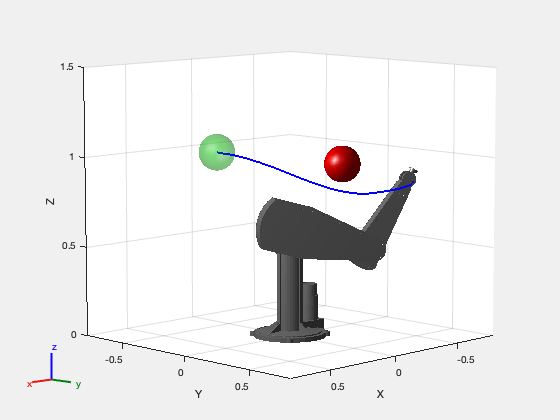

figure(1)
axes = show(robot, config, "Frames","off");
axis([-0.8 0.8 -0.8 0.8 0 1.5]);

% Draw obstacle
[X, Y, Z] = sphere(20);
X = R*X + p_obs(1);
Y = R*Y + p_obs(2);
Z = R*Z + p_obs(3);

s = patch(surf2patch(X, Y, Z));
s.FaceColor = 'red'; 
s.FaceLighting = 'gouraud'; %각 면 간에 조명이 달라지게 해서 곡면으로 보임
s.EdgeAlpha = 0; % 테두리가 없음

% Draw safety volume of the wrist
[X, Y, Z] = sphere(20);
X = R_w*X + InitPos(1);
Y = R_w*Y + InitPos(2);
Z = R_w*Z + InitPos(3);

s = patch(surf2patch(X, Y, Z));
s.FaceColor = 'green'; 
s.FaceLighting = 'gouraud'; %각 면 간에 조명이 달라지게 해서 곡면으로 보임
s.FaceAlpha = 0.3;
s.EdgeAlpha = 0; % 테두리가 없음

figure(1)
hold on
plot3(p_x(1,:), p_y(1,:), p_z(1,:), 'LineWidth', 2, 'Color','b');
for i = 2:50:length(out.tout)
    show(robot, q(1,:,i)', 'Frames', 'off', 'PreservePlot',false);
    % pause(out.tout(i) - out.tout(i-1))
    drawnow
end

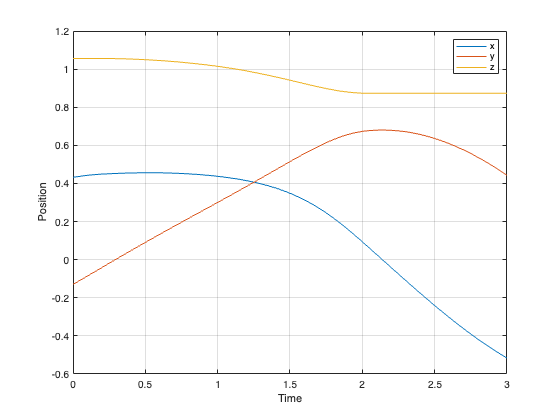


% Plot
figure('Name',['Position of the wirst', '(gamma=', num2str(gamma), ')']);
plot(out.tout, p_x(1,:), out.tout, p_y(1,:),out.tout, p_z(1,:)), grid;
xlabel('Time');
ylabel('Position');
legend('x', 'y', 'z');

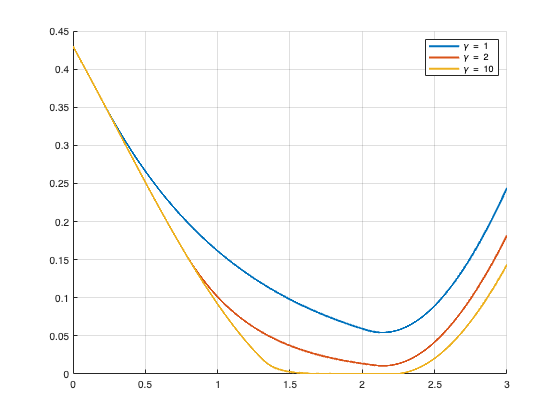


figure('Name','The values of CBF');
for i = 1:num_gamma
    hold on
    plot(out.tout, hx(i, :), 'LineWidth', 2);
end
legend('\gamma = 1', '\gamma = 2', '\gamma = 10')
hold off
grid;

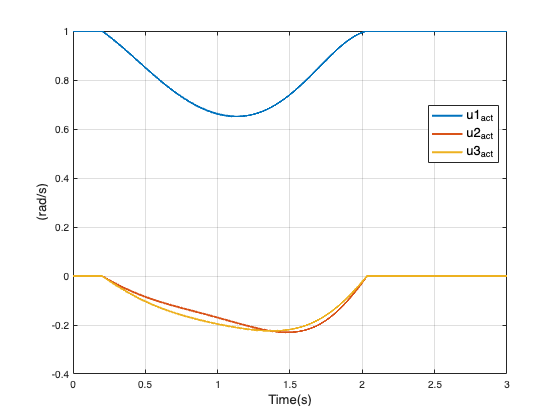


figure('Name','The actuated velocities of the six joints of the manipulator');

plot(out.tout, reshape(u_act(1,1:3, :), [], t_size), 'LineWidth', 2); grid;
xlabel('Time(s)', 'FontSize', 13);
ylabel('(rad/s)', 'FontSize', 13);
legend('u1_{act}', 'u2_{act}', 'u3_{act}', 'Location','best', 'FontSize', 13);